## Module 2 project 17

fsdf

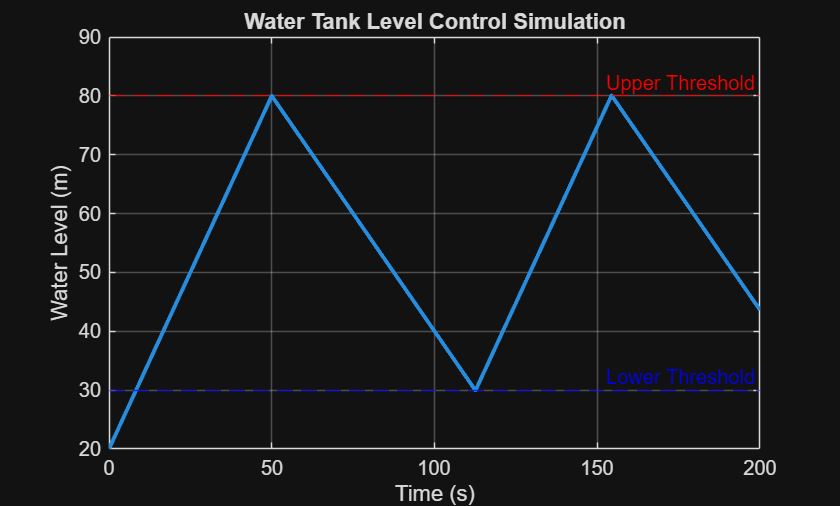

%% Project 17: Water Tank Level Control

% Parameters
dt = 0.1;              % time step (s)
t_end = 200;           % total simulation time (s)
t = 0:dt:t_end;

tank_level = zeros(size(t));
level = 20;            % initial water level (m)
tank_level(1) = level;

% Control thresholds
upper_threshold = 80;  % tank fills until this level
lower_threshold = 30;  % tank drains until this level

% Flow rates (m/s)
inflow = 1.2;          % fill rate
outflow = 0.8;         % drain rate

% Initial mode
filling = true;

for i = 2:length(t) % starts at 2, 1 is the initial tank value

    % Control logic
    if filling
        level = level + inflow * dt;
        if level >= upper_threshold
            filling = false;   % switch to draining
        end
    else
        level = level - outflow * dt;
        if level <= lower_threshold
            filling = true;    % switch to filling
        end
    end

    tank_level(i) = level;
end

%% Plot tank level
figure;
plot(t, tank_level, 'LineWidth', 2)
hold on
yline(upper_threshold, 'r--', 'Upper Threshold')
yline(lower_threshold, 'b--', 'Lower Threshold')
xlabel('Time (s)')
ylabel('Water Level (m)')
title('Water Tank Level Control Simulation')
grid on